C = 357*10^(-6)

C = 3.5700e-04

W = tf(1, [C 0])

W =
 
      1
  ----------
  0.000357 s
 
Continuous-time transfer function.



syms w
Wjw=1/C/j/w

$$Wjw = -\frac{6159729007148459\,\mathrm{i}}{2199023255552\,w}$$

% A1 = sqrt((1/C/1i/w)^2)
A1 = abs(Wjw)

$$A1 = \frac{6159729007148459}{2199023255552\,\left|w\right|}$$

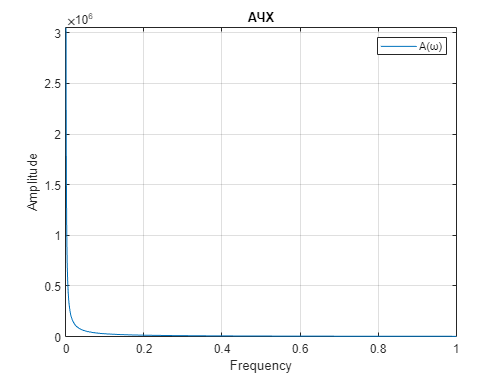

% АЧХ
fplot(A1,[0,1])
grid on
xlabel("Frequency")
ylabel("Amplitude")
title("АЧХ")
legend("A(ω)")


F=atan2(imag(Wjw), real(Wjw))

$$F = \text{atan2}\left(-\mathrm{real}\left(\frac{1}{w}\right),\mathrm{imag}\left(\frac{1}{w}\right)\right)$$

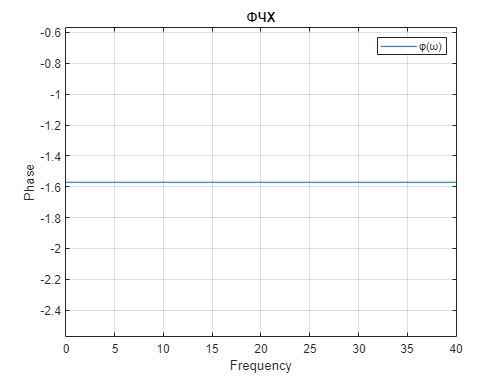

% фчх
fplot(F,[0,40])
grid on
xlabel("Frequency")
ylabel("Phase")
title("ФЧХ")
legend("φ(ω)")

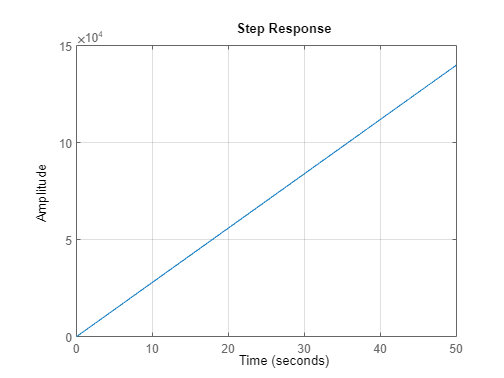

step(W)
grid on

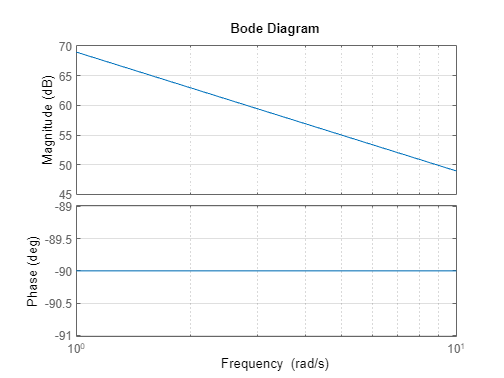

bode(W)
grid on